# Expand Example 3.34:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider a sinusoidal signal that is time-limited in the interval $-\tau<t<\tau$  is given by

        
$$x(t)=\left\{
\begin{array}{c l}
    \cos\left(2\pi f_{0}t\right)\;,
    &\quad -\tau<t<\tau \\
    0\;, &\quad \textrm{otherwise}
  \end{array} 
\right.$$


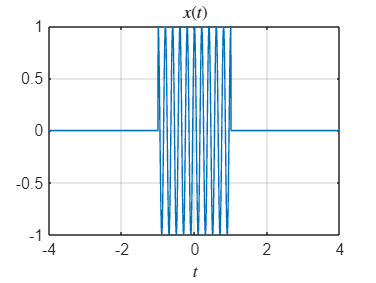

f0 =   5;  % Frequency
tau = 1;
%
t = [-4:0.005:4];
xt = cos(2*pi*f0*t).*((t>=-tau)&(t<=tau));
f = [-12:0.02:12];  % Create a vector of frequencies
% Compute the transform
Xf = tau*sinc(2*tau*(f+f0))+tau*sinc(2*tau*(f-f0));
% Graph the signal and its transform.
plot(t,xt); grid;
set(0,'defaultTextInterpreter','latex');
xlabel('$t$');
title('$x(t)$');

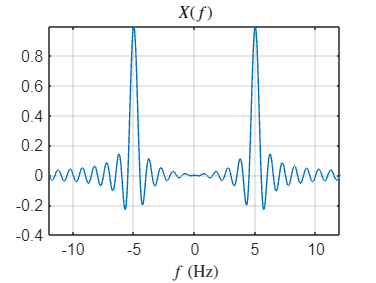

plot(f,Xf); grid;
xlabel('$f$ (Hz)');
title('$X(f)$');

set(0,'defaultTextInterpreter','tex');